folder = "11_04_22/uav_data/*.csv";
files = dir(folder);
display(files)

files = 6×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


file_num = 6; %start at 3
file = importdata(files(file_num).folder + "/" + files(file_num).name, ",");
data = file.data(file.data(:,1) < 2000000, :);

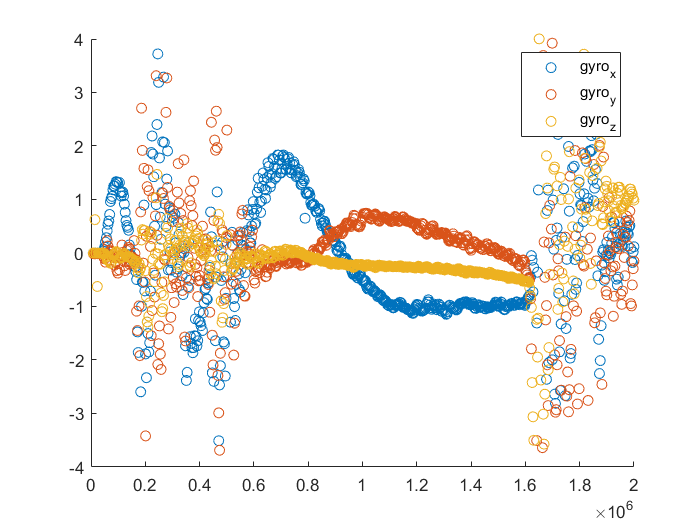

clf
hold on
ylim([-4 4])
scatter(data(:,1), data(:,2))
scatter(data(:,1), data(:,3))
scatter(data(:,1), data(:,4))
legend(file.colheaders(2:4))
hold off

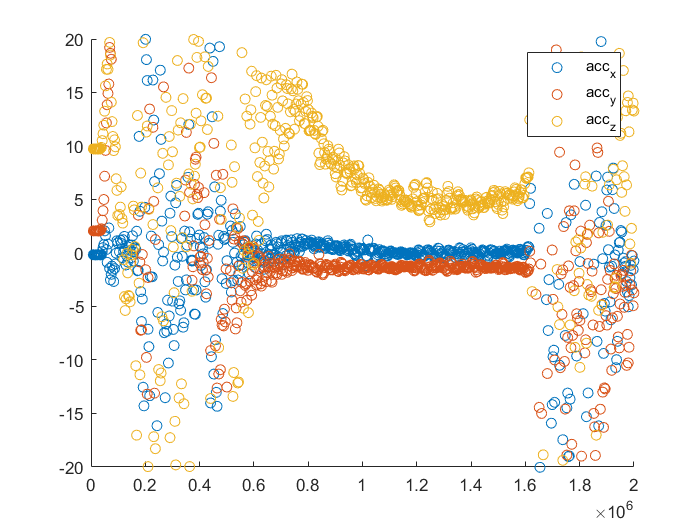

clf
hold on
ylim([-20 20])
scatter(data(:,1), data(:,5))
scatter(data(:,1), data(:,6))
scatter(data(:,1), data(:,7))
legend(file.colheaders(5:7))
hold off

% histogram(1000000./diff(data(:,1)), 100)

% 
% ifilt = imufilter('SampleRate', 333);
% for ii=1:size(imu_data,1)
%     qimu = ifilt(imu_data(ii,5:7), imu_data(ii,2:4));
%     set(poseplot, "Orientation", qimu)
%     drawnow limitrate
% end

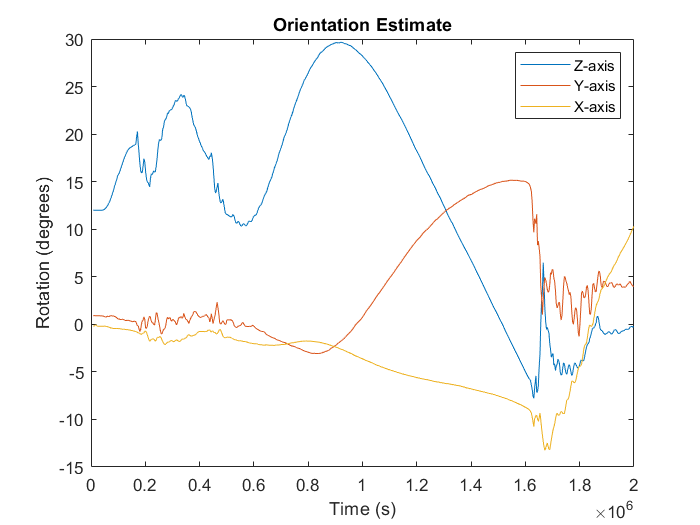

imu_data = data(data(:,1) > 0, :);
ifilt = imufilter('SampleRate', 333, 'LinearAccelerationDecayFactor', 0.9);
a = ifilt(imu_data(:,5:7), imu_data(:,2:4));

time_imu = (0:1:size(imu_data,1)-1)/333;
orientation = eulerd(a,'XYZ','frame');
plot(data(:,1),orientation)
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')

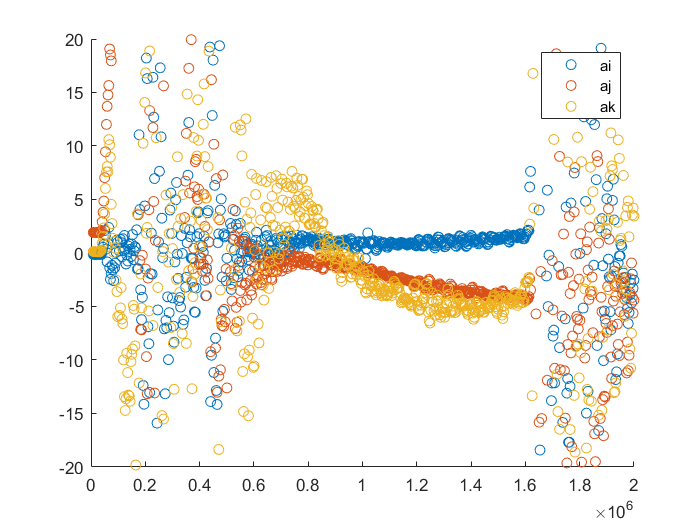

ai = imu_data(:,5) - (9.81 * tand(orientation(:,3)));
aj = imu_data(:,6) - (9.81 * tand(orientation(:,2)));
ak = imu_data(:,7) - (9.81 * cosd(orientation(:,1)));
clf
hold on
ylim([-20 20])
scatter(data(:,1), ai, 'DisplayName', "ai")
scatter(data(:,1), aj, 'DisplayName', "aj")
scatter(data(:,1), ak, 'DisplayName', "ak")
hold off
legend

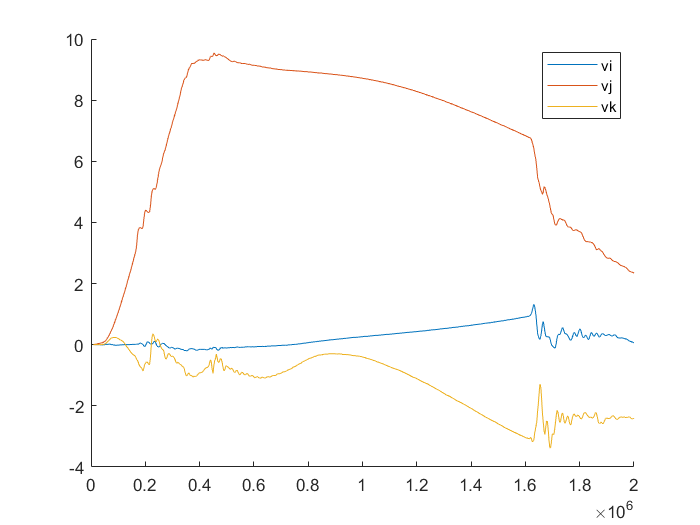

clf
vi = cumtrapz(imu_data(:,1)./1e6, ai);
vj = cumtrapz(imu_data(:,1)./1e6, aj);
vk = cumtrapz(imu_data(:,1)./1e6, ak);
hold on
plot(data(:,1), vi, 'DisplayName', "vi")
plot(data(:,1), vj, 'DisplayName', "vj")
plot(data(:,1), vk, 'DisplayName', "vk")
hold off
legend

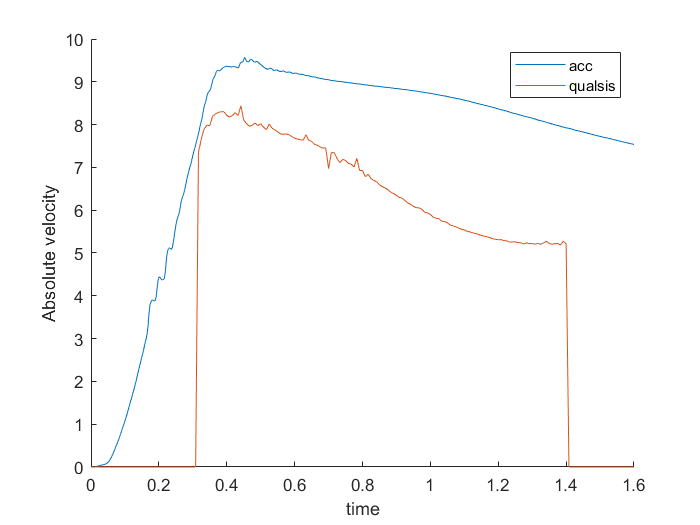

clf
v = [vi,vj,vk];
xlim([0,1.6])
hold on
plot(data(:,1)/1e6, vecnorm(v'), 'DisplayName', "acc")
plot(time(time>7)-7.5, absVelocity(time>7), 'DisplayName', "qualsis")
hold off
legend
xlabel("time")
ylabel("Absolute velocity")

clf
ke = cumtrapz(0.5*0.250*(vecnorm(v')).^2)

ke = 	1.0e+03 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0011    0.0013    0.0015    0.0018    0.0021    0.0025    0.0029    0.0033    0.0038    0.0043    0.0049    0.0055    0.0062    0.0069    0.0077    0.0085    0.0095    0.0105


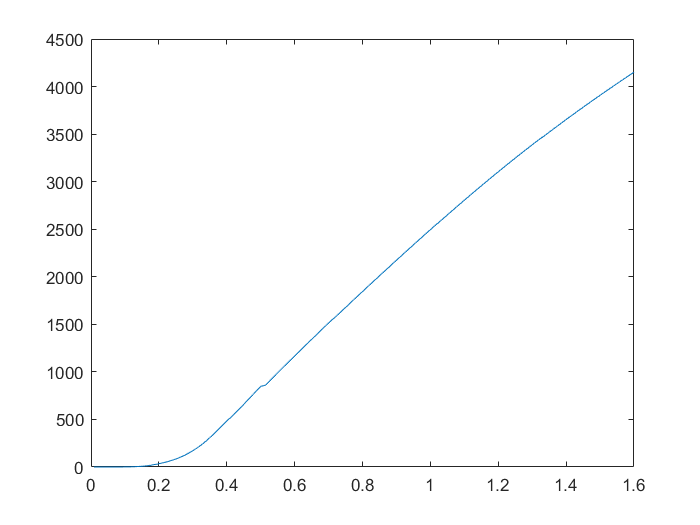

plot(data(:,1)./1e6, ke)
xlim([0, 1.6])

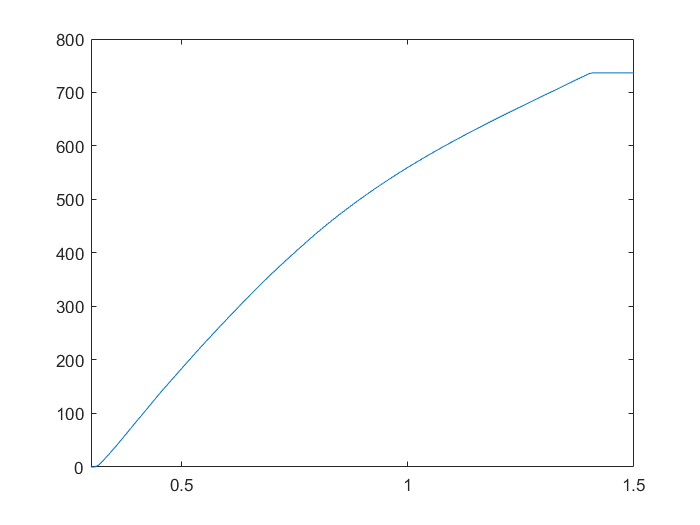

clf
absVelocity(isnan(absVelocity))=0;
ke = cumtrapz(0.5*0.250*(absVelocity(time>7)).^2);
plot(time(time>7)-7.5, ke)
xlim([0.3, 1.5])